# Control of a 3 DOF Mechanical Crane

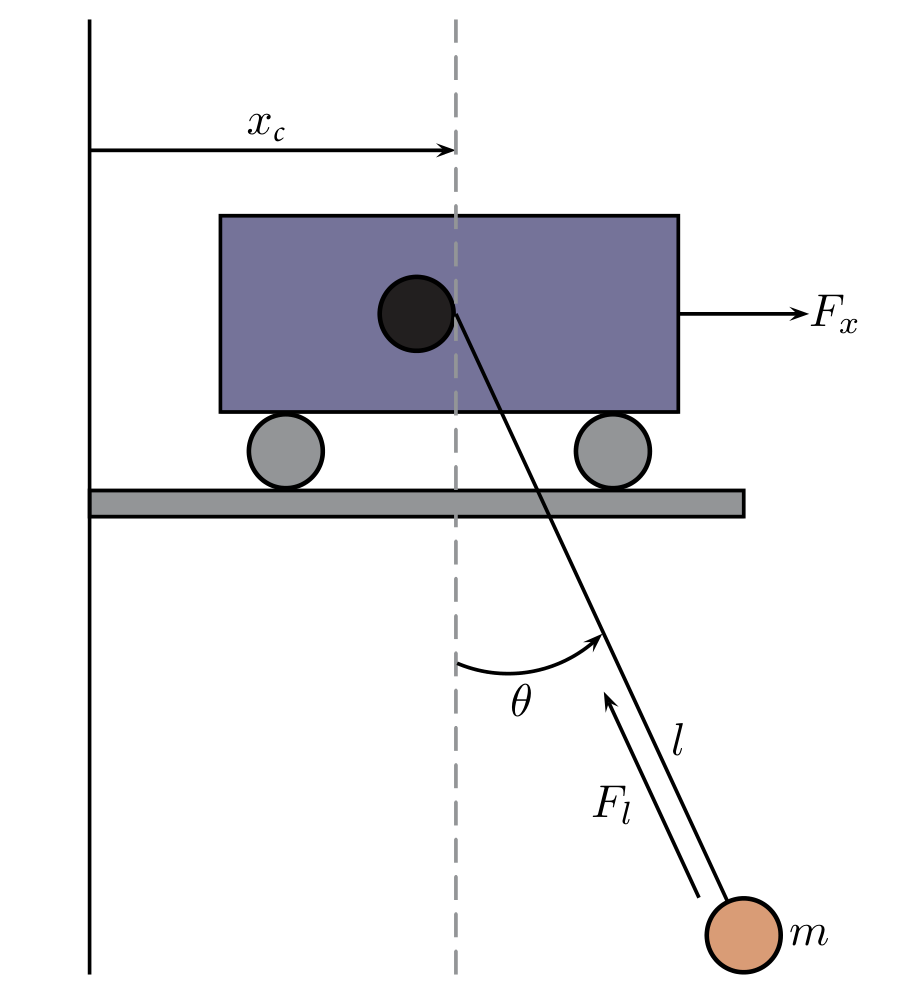

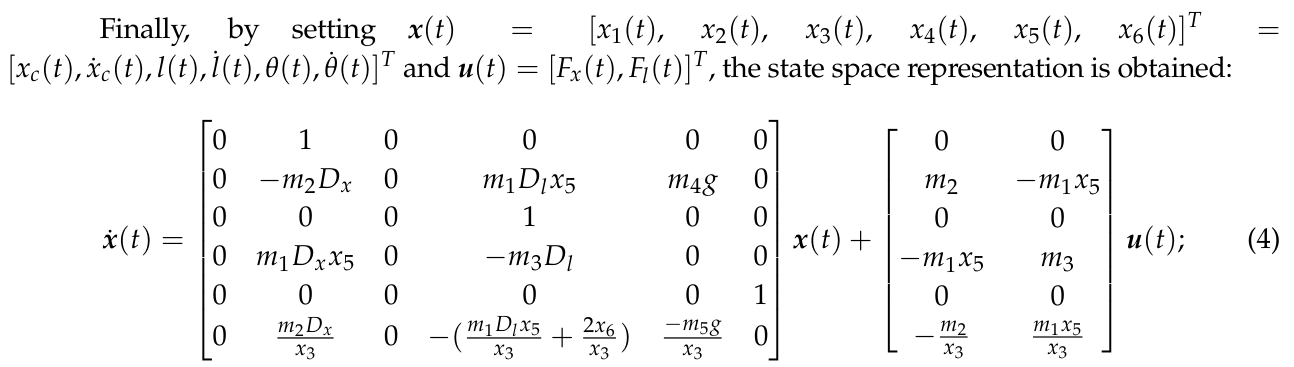

Reference paper: [Robust qLPV Tracking Fault-Tolerant Control of a 3 DOF Mechanical Crane | MDPI](https://www.mdpi.com/2297-8747/25/3/48)

% A_nl = [0 1 0 0 0 0; 
%         0 -m2*Dx 0 m1*Dl*x5 m4*g 0;
%         0 0 0 1 0 0;
%         0 m1*Dx*x5 0 -m3*Dl 0 0;
%         0 0 0 0 0 1;
%         0 m2*Dx/x3 0 -[(m1*Dl*x5)/x5 + 2*x6/x3] -m5*g/x3 0]
% 
% B_nl = [0 0;
%         m2 -m1*x5;
%         0 0;
%         -m1*x5 m3;
%         0 0;
%         -m2/x3 m1*x5/x3]


## Parameters

- m is the load mass 

- g is the gravitational acceleration; 

- Dx and Dy are the viscous damping coefficients associated with the x- and z-axis respectively; 

- finally, Mx and Ml are the traveling and hoisting components of the crane mass, respectively, i.e., Mx = m + mc and Ml = m, where mc is the cart mass.

Initial Conditions: x(0) = 0, l(0) = 0.22 [m], θ(0) = 0

g = 9.81;
m = 0.50; %Kg
Mx = 1.655; %Kg
Ml = 0.50; %Kg
Dx = 100; %Ns/m
Dl = 82; %Ns/m

m1 = m/(Ml*Mx + Mx*m);
m2 = (Ml+m)/(Ml*Mx+Mx*m);
m3 = Mx/(Ml*Mx + Mx*m);
m4 = m*(Ml + m)/(Ml*Mx + Mx*m); 
m5 = (Mx*Ml + Ml*m + Mx*m + m2)/(Ml*Mx + Mx*m);

syms x1 x2 x3 x4 x5 x6 u1 u2

A_nl = [0 1 0 0 0 0; 
        0 -m2*Dx 0 m1*Dl*x5 m4*g 0;
        0 0 0 1 0 0;
        0 m1*Dx*x5 0 -m3*Dl 0 0;
        0 0 0 0 0 1;
        0 m2*Dx/x3 0 -((m1*Dl*x5)/x5 + 2*x6/x3) -m5*g/x3 0]

$$A\_nl = \left(\begin{array}{cccccc} 0 & 1 & 0 & 0 & 0 & 0\\ 0 & -\frac{20000}{331} & 0 & \frac{8200\,x_{5}}{331} & \frac{981}{331} & 0\\ 0 & 0 & 0 & 1 & 0 & 0\\ 0 & \frac{10000\,x_{5}}{331} & 0 & -82 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 1\\ 0 & \frac{20000}{331\,x_{3}} & 0 & -\frac{2\,x_{6}}{x_{3}}-\frac{8200}{331} & -\frac{1046625262390643}{70368744177664\,x_{3}} & 0 \end{array}\right)$$


B_nl = [0 0;
        m2 -m1*x5;
        0 0;
        -m1*x5 m3;
        0 0;
        -m2/x3 m1*x5/x3]

$$B\_nl = \left(\begin{array}{cc} 0 & 0\\ \frac{200}{331} & -\frac{100\,x_{5}}{331}\\ 0 & 0\\ -\frac{100\,x_{5}}{331} & 1\\ 0 & 0\\ -\frac{200}{331\,x_{3}} & \frac{100\,x_{5}}{331\,x_{3}} \end{array}\right)$$

X = [x1 x2 x3 x4 x5 x6];
U = [u1 u2];

F = A_nl * X' + B_nl * U';
A = jacobian(F, X)

$$A = \left(\begin{array}{cccccc} 0 & 1 & 0 & 0 & 0 & 0\\ 0 & -\frac{20000}{331} & 0 & \frac{8200\,x_{5}}{331} & \frac{8200\,\bar{x_{4}}}{331}-\frac{100\,\bar{u_{2}}}{331}+\frac{981}{331} & 0\\ 0 & 0 & 0 & 1 & 0 & 0\\ 0 & \frac{10000\,x_{5}}{331} & 0 & -82 & \frac{10000\,\bar{x_{2}}}{331}-\frac{100\,\bar{u_{1}}}{331} & 0\\ 0 & 0 & 0 & 0 & 0 & 1\\ 0 & \frac{20000}{331\,x_{3}} & \frac{200\,\bar{u_{1}}}{331\,{x_{3}}^{2}}-\frac{20000\,\bar{x_{2}}}{331\,{x_{3}}^{2}}+\frac{1046625262390643\,\bar{x_{5}}}{70368744177664\,{x_{3}}^{2}}-\frac{100\,x_{5}\,\bar{u_{2}}}{331\,{x_{3}}^{2}}+\frac{2\,x_{6}\,\bar{x_{4}}}{{x_{3}}^{2}} & -\frac{2\,x_{6}}{x_{3}}-\frac{8200}{331} & \frac{100\,\bar{u_{2}}}{331\,x_{3}}-\frac{1046625262390643}{70368744177664\,x_{3}} & -\frac{2\,\bar{x_{4}}}{x_{3}} \end{array}\right)$$

B = jacobian(F, U)

$$B = \left(\begin{array}{cc} 0 & 0\\ \frac{200}{331} & -\frac{100\,x_{5}}{331}\\ 0 & 0\\ -\frac{100\,x_{5}}{331} & 1\\ 0 & 0\\ -\frac{200}{331\,x_{3}} & \frac{100\,x_{5}}{331\,x_{3}} \end{array}\right)$$


% Substitute operating point (example: x1=0, x2=0, u=2)
operating_point = [0, 0, 0.22, 0, 0, 0, 0, 0]; % [x1, x2, x3, x4, x5, x6, u1, u2]
A_lin = subs(A, [x1, x2, x3, x4, x5, x6, u1, u2], operating_point);
B_lin = subs(B, [x1, x2, x3, x4, x5, x6, u1, u2], operating_point);

% Display the linearized matrices
disp('A_lin matrix:');

A_lin matrix:


disp(vpa(A_lin));

$$\left(\begin{array}{cccccc} 0 & 1.0 & 0 & 0 & 0 & 0\\ 0 & -60.422960725075528700906344410876 & 0 & 0 & 2.9637462235649546827794561933535 & 0\\ 0 & 0 & 0 & 1.0 & 0 & 0\\ 0 & 0 & 0 & -82.0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 1.0\\ 0 & 274.64982147761603954957429277671 & 0 & -24.773413897280966767371601208459 & -67.606543386789106555376995608888 & 0 \end{array}\right)$$

disp('B_lin matrix:');

B_lin matrix:


disp(vpa(B_lin));

$$\left(\begin{array}{cc} 0 & 0\\ 0.60422960725075528700906344410876 & 0\\ 0 & 0\\ 0 & 1.0\\ 0 & 0\\ -2.7464982147761603954957429277671 & 0 \end{array}\right)$$


C = eye(6);
D = zeros(6,2);

## Stabilità

eigenvalues = eig(A_lin);

% Check stability
if isAlways(real(eigenvalues) < 0) % Continuous-time stability criteria
    disp('The matrix is Asynt stable (continuous-time system).');
elseif isAlways(abs(eigenvalues) < 1) % Discrete-time stability criteria
    disp('The matrix is stable (discrete-time system).');
elseif isAlways(real(eigenvalues) <= 0)
    disp('The matrix is stable.');
end

The matrix is stable.


vpa_eigenvalues = vpa(eigenvalues);
% Display eigenvalues
disp('Eigenvalues:');

Eigenvalues:


disp(vpa_eigenvalues);

$$\left(\begin{array}{c} -82.0\\ 0\\ 0\\ -60.20248282930712629915218878184\\ -0.11023894788420120087707781451829-7.3702831714201781417034417438823\,\mathrm{i}\\ -0.11023894788420120087707781451829+7.3702831714201781417034417438823\,\mathrm{i} \end{array}\right)$$

var2 = double(eigenvalues);
disp(var2)

 -82.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
 -60.2025 + 0.0000i
  -0.1102 - 7.3703i
  -0.1102 + 7.3703i



var = vpa(vpa_eigenvalues);

## Controllabilità

disp('---------------- Controllability ------------------');

---------------- Controllability ------------------


% Calculate the controllability matrix
ControllabilityMatrix = ctrb(double(A_lin), double(B_lin));
% Check the rank of the controllability matrix
rank_of_CM = rank(ControllabilityMatrix)

rank_of_CM = 6


if rank_of_CM == size(double(A_lin), 1)
    disp('The system is controllable.');
else
    disp('The system is NOT controllable.');
end

The system is controllable.


## Osservabilità

disp('----------------------------------');

----------------------------------


% Calcolare la matrice di osservabilità
Q_o = obsv(double(A_lin), C);
% Verificare il rango della matrice di osservabilità
rank_Q_o = rank(Q_o)

rank_Q_o = 6


if rank_Q_o == size(A, 1)
    disp('Il sistema è osservabile.');
else
    disp('Il sistema NON è osservabile.');
end

Il sistema è osservabile.


## State Feedback con Osservatore e Integratore


disp('---------------STATE FEEDBACK con Observer and Integrator -------------------');

---------------STATE FEEDBACK con Observer and Integrator -------------------



% Load Modello e Parametri
load("model.mat");

% Autovalori desiderati
desired_eigenvalues = [-1 -0.5 -0.5 -0.25 -1.25 -3]; 

% Calcolo del guadagno di feedback
K = place(double(A_lin), double(B_lin), desired_eigenvalues);

% Matrice ad anello chiuso
A_closed_loop = double(A_lin) - double(B_lin) * K;

double_A = double(A_lin);
double_B = double(B_lin);
C = [1 0 0 0 0 0; 0 0 1 0 0 0; 0 0 0 0 1 0];

C_int = [ 1 0 0 0 0 0; 0 0 1 0 0 0];

D = zeros(3,2);
Kf = pinv(C*inv(A_closed_loop)*double_B);

% Condizioni iniziali
x0 = [1, 0, 0.62, 0, 0, 0]';
x0_Aug = [1, 0, 0.62, 0, 0, 0, 0, 0]';
xd = [2; 0.42; 0];
xd_aug = [2; 0.42];

%Condizione per aggiungere l'integratore
Ctrb = ctrb(A_lin,B_lin); %rank(Ctrb)
controllabile = rank(Ctrb) == size(double_A, 1);

if controllabile
    disp('Il sistema è controllabile.');
else
    disp('Il sistema NON è controllabile.');
end

Il sistema è controllabile.



Sys_aug = [double_A double_B; -C_int zeros(2,2)]; 
rank(Sys_aug)

ans = 8

uguale = rank(Sys_aug) == size(double_A, 1)+2;

if uguale & controllabile
    disp('Possiamo aggiungere l integratore.');
else
    disp('Il sistema aumentato non può essere creato.');
end

Possiamo aggiungere l integratore.



%Confermato che si può, costruiamo il sistema aumentato
A_aug = [double_A zeros(6,2); -C_int zeros(2,2)]; %rank(A_aug) 
B_aug = [double_B; zeros(2,2)];
C_aug = [C_int zeros(2,2)];
D_aug = zeros(2,2);

rank(A_aug)

ans = 6

rank(B_aug)

ans = 2

Co_aug = ctrb(A_aug, B_aug);
rank(Co_aug)

ans = 4

Obs_aug = obsv(A_aug, C_aug);
rank(Obs_aug)

ans = 6


% Autovalori desiderati - 
% autovalori dell’integratore con modulo circa 2–5 volte quello del polo inferiore 
% desired_eigenvalues_i = [-1 -0.5 -0.5 -0.25 -1.25 -3 -62 -83];
desired_eigenvalues_i = [-1 -0.5 -0.5 -0.25 -1.25 -3 -6 -13.795];

% Calcolo del guadagno di feedback
K_i = place(A_aug, B_aug, desired_eigenvalues_i);

poli_osservatore = [-100 -50 -50 -25 -125 -300];

% Calcolo del guadagno dell'osservatore L
L = place(double_A', C', poli_osservatore)';

% Dinamica dell'osservatore
A_o = double_A - L * C; % Matrice del sistema osservatore
B_o = [double_B - L * D, L]; % Matrice degli ingressi per l'osservatore
C_o = eye(6); % Gli stati stimati vengono restituiti
D_o = zeros(6,5); % Dimensioni appropriate per ingressi e uscite

ST=25;
% out_SFOI_D = sim("Script_Tesina/State_Feedback_Osservatore_Integratore.slx");

% d_const = [2;-0.4];
% out_SFOI_D = sim("Script_Tesina/State_Feedback_Osservatore_Integratore_D_const_V2.slx");

DI = 5;
out_SFOI_D = sim("Script_Tesina/State_Feedback_Osservatore_Integratore_DI_V2.slx");

% out_SFOI_D = sim("Script_Tesina/State_Feedback_Osservatore_Integratore_R.slx");

% ------------ plot................
% Estrai time vector e uscite
t_analisi  = out_SFOI_D.tout;
y1 = out_SFOI_D.x_sm.Data-1;  % carrello
y5 = out_SFOI_D.theta_sm.Data*180/3.14;  % massa

% 1) Settling time carrello
S1 = stepinfo(y1, t_analisi, ...
              'SettlingTimeThreshold', 0.01, ...
              'RiseTimeLimits',[0.1 0.9]);  
Ta1 = S1.SettlingTime;
PO1 = S1.Overshoot;
% 2) Peak swing massa
theta_peak = max(abs(y5));          % ampiezza massima [deg]

% Stampa
fprintf('Ta,1 (carrello) = %.2fs  (≤ 15s?)\n', Ta1);

Ta,1 (carrello) = 10.89s  (≤ 15s?)


fprintf('PO1 (carrello) = %.2f%% (≤ 3%%?)\n', PO1);

PO1 (carrello) = 0.21% (≤ 3%?)


fprintf('Peak swing = %.3f deg\n', theta_peak);

Peak swing = 5.681 deg


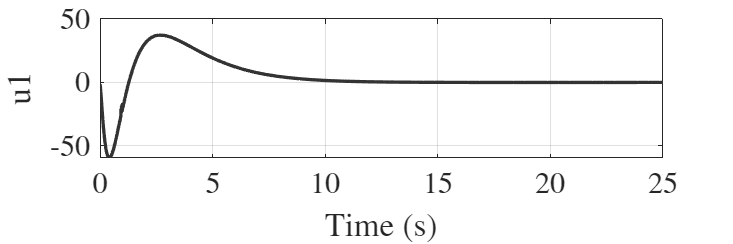

 
personal_plot6(out_SFOI_D.tout,out_SFOI_D.u1.Data,'Time (s)','u1');

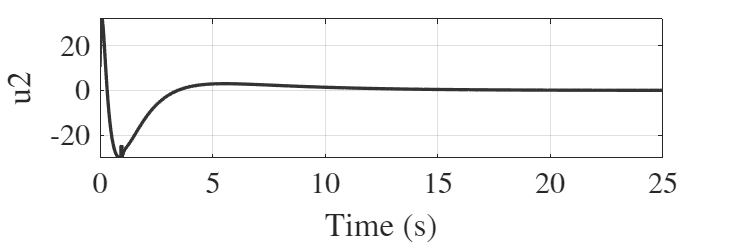

personal_plot6(out_SFOI_D.tout,out_SFOI_D.u2.Data,'Time (s)','u2');

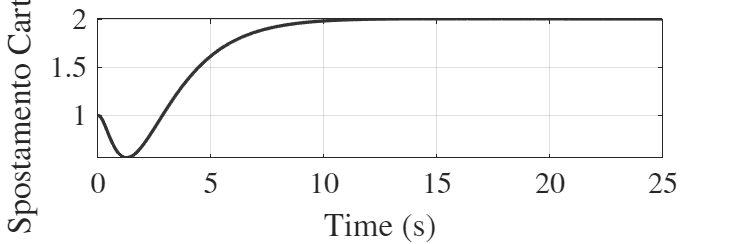

personal_plot6(out_SFOI_D.tout,out_SFOI_D.x_sm.Data,'Time (s)','Spostamento Cart (m)');

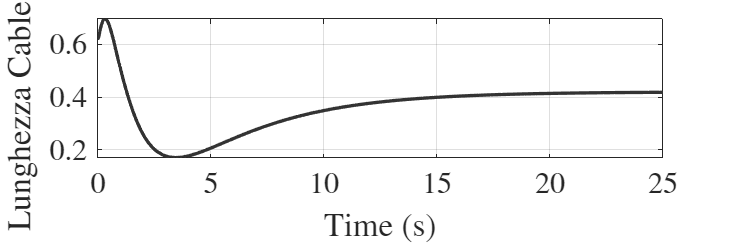

personal_plot6(out_SFOI_D.tout,out_SFOI_D.l_sm.Data,'Time (s)','Lunghezza Cable (m)');

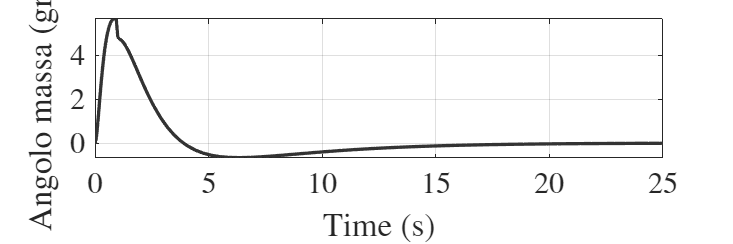

personal_plot6(out_SFOI_D.tout, out_SFOI_D.theta_sm.Data*180/pi,'Time (s)','Angolo massa (gradi)');

## LQG + Integratore

disp('--------------- LQG con I -------------------');

--------------- LQG con I -------------------



 load("model.mat");

double_A = double(A_lin);
double_B = double(B_lin);
C = [1 0 0 0 0 0; 0 0 1 0 0 0; 0 0 0 0 1 0];
D = zeros(3,2);
disp('----------------------------------');

----------------------------------



x0 = [1, 0, 0.62, 0, 0, 0]';
xd = [2; 0.42];

%% Ta<18 PO<3 PS<6°
q_weight = [1/(10.0)^2, 1/(45.00)^2, 1/(20)^2, 1/(10)^2, 1/(20)^2,  1/(2)^2, 0.001, 0.009];
r_weight = [1/(300)^2, 1/(250)^2];

Q_init = diag(q_weight);
R_init = diag(r_weight);

C_int = [ 1 0 0 0 0 0; 0 0 1 0 0 0];

Ai = [double_A zeros(6,2); -C_int zeros(2,2)];
Bi = [ double_B; zeros(2,2)];
Ci = [C_int zeros(2,2)];
Di = zeros(2,2);

Sys_aug = [double_A double_B; -C_int zeros(2,2)]; 
rank(Sys_aug)

ans = 8

Co_aug = ctrb(Ai, Bi);
rank(Co_aug)

ans = 4


sys_i = ss(Ai, Bi, [], []);

K = lqi(sys_i, Q_init, R_init); 

%Kalman
state_cov = 0.50 * eye(6); 
output_cov = 0.01 * eye(3);

% LQE = Filtro di Kalman in tempo continuo
[L_Kalman, ~, ~] = lqe(double_A, eye(6), C, state_cov, output_cov);

% Nuovo sistema controllato
A_cl = Ai - Bi * K;
eig(A_cl);   % verifica la stabilità

A_obs = double_A - L_Kalman * C;
eig(A_obs);
B_obs = [double_B L_Kalman];

% SIM ----------------------------------------------------------------
ST=80;

out_LQGI = sim("Script_Tesina/SFOI_LQG.slx");
% d_const = [2;-0.4];
% out_LQGI = sim("Script_Tesina/SFOI_LQG_DC_VOL2.slx");
% DI = 5;
% out_LQGI = sim("Script_Tesina/SFOI_LQG_DI.slx");
% out_LQGI = sim("Script_Tesina/SFOI_LQG_R.slx");

% PLOT ----------------------------------------------------------------

% Estrai time vector e uscite
t  = out_LQGI.tout;
y1 = out_LQGI.x_sm.Data-1;  % carrello
y5 = out_LQGI.theta_sm.Data*180/3.14;  % massa

% 1) Settling time carrello
S1 = stepinfo(y1, t, ...
              'SettlingTimeThreshold', 0.02, ...
              'RiseTimeLimits',[0.1 0.9]);  
Ta1 = S1.SettlingTime;
PO1 = S1.Overshoot;

% Stampa
fprintf('Ta,1 (carrello) = %.2fs  (≤ 15s?)\n', Ta1);

Ta,1 (carrello) = 16.81s  (≤ 15s?)


fprintf('PO1 (carrello) = %.2f%% (≤ 3%%?)\n', PO1);

PO1 (carrello) = 0.68% (≤ 3%?)



% 2) Peak swing massa
theta_peak = max(abs(y5));          % ampiezza massima [rad]
fprintf('Peak swing = %.3f deg\n', theta_peak);

Peak swing = 5.987 deg



% 3) Settling time massa (manuale)
tol_deg   = 0.02;                        % specifica: ±1°
err_theta = abs(y5);
% Trovo l'ultimo istante in cui supero la tolleranza
idx_last  = find(err_theta > tol_deg, 1, 'last');

if isempty(idx_last)
    Ts_theta = 0;   % mai fuori dalla banda: già a regime dall'inizio
else
    Ts_theta = t(idx_last);
end

fprintf('Ta,5 (massa) = %.2fs  (entro ±%d°)\n', Ts_theta, tol_deg);

Ta,5 (massa) = 18.36s  (entro ±2.000000e-02°)


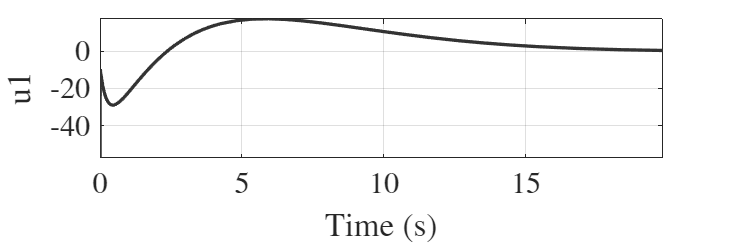


t1 = out_LQGI.tout(out_LQGI.tout<20,1);
personal_plot6(t1,out_LQGI.u.Data(1:length(t1),1),'Time (s)','u1');

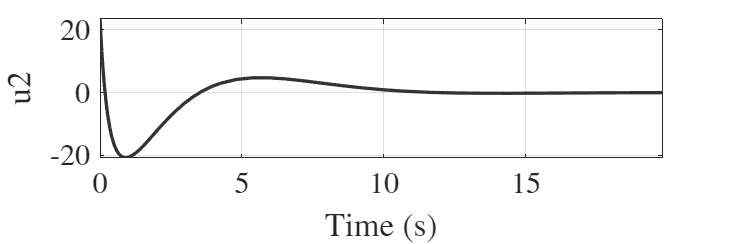

personal_plot6(t1,out_LQGI.u.Data(1:length(t1),2),'Time (s)','u2');

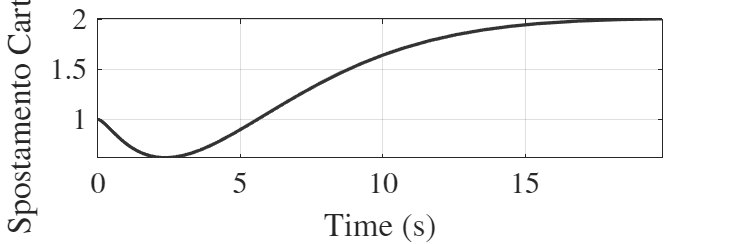

personal_plot6(t1,out_LQGI.x_sm.Data(1:length(t1)),'Time (s)','Spostamento Cart (m)');

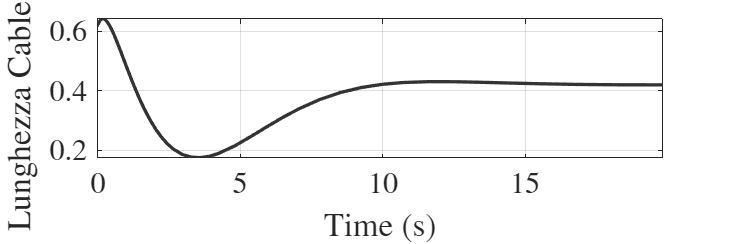

personal_plot6(t1,out_LQGI.l_sm.Data(1:length(t1)),'Time (s)','Lunghezza Cable (m)');

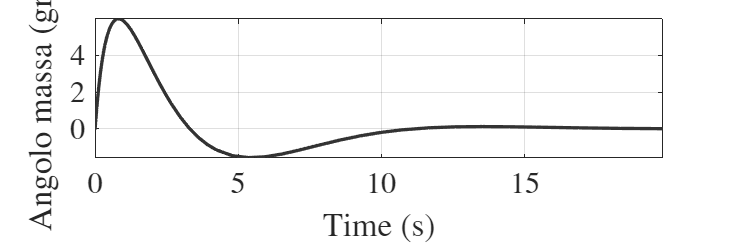

personal_plot6(t1, out_LQGI.theta_sm.Data(1:length(t1))*180/3.14,'Time (s)','Angolo massa (gradi)');